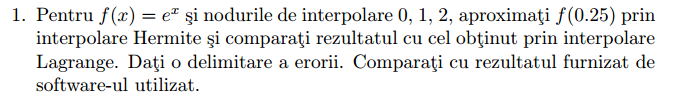

O delimitare a erorii este reprezentata de:

$R_n(x) = \frac{f^{(n+1)}(\eta)}{6!} * \Pi_{i=1}^{k}{(x - x_i)^2}, \eta \in [min(x), max(x)]$, k = nr. noduri de interpolare, n = gradul de interpolare.

Pentru $f(x) = e^x \Rightarrow f^{(n)}(x) = e^x$ si $\eta \in [0, 2]$:

    $max(e^\eta) = e^2$ si gradul de interpolare n = 2*k-1 = 5


$$\Rightarrow = |R_5(0.25)| \leq \frac{e^2}{720} * (0.25 - 0)^2 * (0.25 - 1)^2 * (0.25 -2)^2$$


f = @(x) exp(x);
x = [0 1 2];
xx = 0.25;

## Hermite Interpolation

y = f(x);
dy = f(x);

[H, Q] = HermitePowell(x, y, dy, xx);
fprintf("[APPROX_HERMITE] f(%.2f) = %.16f\n", xx, H);

[APPROX_HERMITE] f(0.25) = 1.2836450992199067


## Lagrange Interpolation (classic)

Lm = Lagrange(xx, x, y);
fprintf("[APPROX_LAGRANGE] f(%.2f) = %.16f\n", xx, Lm);

[APPROX_LAGRANGE] f(0.25) = 1.1527742906760841


## Result Comparison

real_val = f(xx);

abs_herm_vs_lag = abs(H - Lm);
abs_real_vs_herm = abs(real_val - H);
abs_real_vs_lag = abs(real_val - Lm);

fprintf("REAL f(%.2f) = %.16f\n", xx, real_val);

REAL f(0.25) = 1.2840254166877414


fprintf("ABSOLUTE ERROR HERMITE VS LAGRANGE = %.16e\n", abs_herm_vs_lag);

ABSOLUTE ERROR HERMITE VS LAGRANGE = 1.3087080854382260e-01


fprintf("ABSOLUTE ERROR REAL VS HERMITE = %.16e\n", abs_real_vs_herm);

ABSOLUTE ERROR REAL VS HERMITE = 3.8031746783473430e-04


fprintf("ABSOLUTE ERROR REAL VS LAGRANGE = %.16e\n", abs_real_vs_lag);

ABSOLUTE ERROR REAL VS LAGRANGE = 1.3125112601165734e-01



err_bound = exp(2)/factorial(6) * (0.25^2)*(0.25-1)^2*(0.25-2)^2;
fprintf("ERROR BOUND = %.16e\n", err_bound)

ERROR BOUND = 1.1049308741687069e-03
